% Real value, a = 2
% Imaginary value, b = 5
% Complex number, C = a+i*b
a = 2; b = 5;
C = a + i*b

C = 2.0000 + 5.0000i

% Real value, a = 2
% Imaginary value, b = 5
% Complex number, C = a+i*b
a = 2; b = 5;
C = complex(a,b)

C = 2.0000 + 5.0000i

% Complex number, C = a+i*b = 2+5i
a = 2; b = 5;
C = complex(a,b);
[C_angle, C_mag] = cart2pol(a,b);
C_angle = C_angle*(180/pi); %in degree
C_polar = [C_mag, C_angle];

a = 2; b = 5;
C_mag = sqrt(a^2+b^2);
C_angle = atan(b/a) * (180/pi); % in degree
C_polar = [C_mag, C_angle]

C_polar =     5.3852   68.1986


% Complec number, C = a+i*b = 2+5i
a = 2; b = 5;
C = complex(a,b);
C_mag = abs(C);
C_angle = angle(C)*(180/pi); % in degree
C_polar = [C_mag, C_angle]

C_polar =     5.3852   68.1986


Euler's Series

Euler's formular

$e^{\textrm{ix}}$ = cos x + isin x

% C1 = 2+5i
% C2 = 5+10i
% Convert C1 and C2 into exponential form
% Determine M =C1*C2 and D = C1/C2 in exponential form

C1 = complex(2, 5);
C2 = complex(5, 10);
C1_mag = abs(C1);
C1_angle = angle(C1);
C2_mag = abs(C2);
C2_angle = angle(C2);

% C = a+bi = |C| (cos(theta) + i*sin(theta)) = |C|exp(i*theta)
disp(['C1 in exponential form: ', num2str(C1_mag), 'exp(i*', num2str(C1_angle), ')']);

C1 in exponential form: 5.3852exp(i*1.1903)


disp(['C1 in exponential form: ', num2str(C2_mag), 'exp(i*', num2str(C2_angle), ')']);

C1 in exponential form: 11.1803exp(i*1.1071)



% C1*C2
M_mag = C1_mag*C2_mag;
M_angle = C1_angle + C2_angle;
disp(['C1/C2 in exponential form: ', num2str(M_mag), 'exp(i*', num2str(M_angle), ')']);

C1/C2 in exponential form: 60.208exp(i*2.2974)



% C1/C2
D_mag = C1_mag/C2_mag;
D_angle = C1_angle - C2_angle;
disp(['C1/C2 in exponential form: ', num2str(D_mag), 'exp(i*', num2str(D_angle), ')']);

C1/C2 in exponential form: 0.48166exp(i*0.083141)


Creating a function to perform Euler integration

function Sol = Euler_series(f, L, U, N, y1)
% Input parameters
% f: A function that provides the differential equation
% L: Lower limit of X
% U: Upper limit of X
% N: Number of steps 
% y1: Initial value of y
% Output Parameters:
% Sol: [x,y]; x: abscissas; y: ordinate

% Consider the step size, h

h = (U-L)/N;
y = zeros(N+1, 1);
x = zeros(N+1, 1);
x(1) = L;
y(1) = y1;

for i = 1:N
    y(i+1) = y(i) + h*f(x(i), y(i));
    x(i+1) = x(1) + i+h;
end

plot(x, y, '*');
grid on;
xlabel('x');
ylabel('y');
title('Differential equation: dy/dx = 2x^2+y-2;0<=x<=5;y(0)=0.1');
Sol = [x,y];
end

clc; 

% Generate a function for the differential equation
% Differential equation: dy/dx = 2x^2+y-2 
% Condition 0 <= x <= 5; y(0) = 0.1
% N.B> Matlab iterate from 1, not from 0.
% Hence, for initial value y(0), we will consider it y(1).
% Number of step, N=18
% Number of steps, N=18

f = @(x,y) 2*x^2+y-2;
L = input('Enter the lower limit of x:');
U = input('Enter the upper limit of x:');
N = input('Enter the number of step:');
y1 = input('Enter initial value of y:');
Euler_series(f, L, U, N, y1)

Error using  / 
Matrix dimensions must agree.

Error in Complex_numbers>Euler_series (line 65)
h = (U-L)/N;

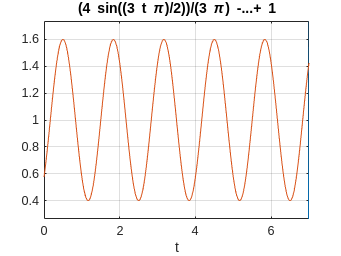



clc;
% input: Square wave function
% T = 2; Magnitude = 1; Omega = pi
t = -7:0.01:7;
x = 1-square(pi*(t+1));
plot(t,x, 'LineWidth',1.5)
grid on;
hold on;

% Fourier Series
syms k t 
omega = pi;
T = 2;
k = 1.5;
a_0 = (2/T)*int(2,t,0,1);
a_k = (2/T)*int(2*cos(k*omega*t),t,0,1);
b_k = (2/T)*int(2*sin(k*omega*t),t,0,1);
f = (a_0/2)+sum(a_k.*cos(k*omega*t)) + sum(b_k.*sin(k*omega*t));
ezplot(f, [0,7])
grid on

 clc;
 disp('Input sequence: ');

Input sequence: 


 x = [1 4 5 7]

x =      1     4     5     7


 F = fft(x)

F =   17.0000 + 0.0000i  -4.0000 + 3.0000i  -5.0000 + 0.0000i  -4.0000 - 3.0000i


 disp('Fourier transform of x: ');

Fourier transform of x: 


 F

F =   17.0000 + 0.0000i  -4.0000 + 3.0000i  -5.0000 + 0.0000i  -4.0000 - 3.0000i


 inv_F = ifft(F);
 disp('Inverse Fourier transform of F: ');

Inverse Fourier transform of F: 


 inv_F

inv_F =      1     4     5     7


clc;
% Taylor series expansion
% Function: f(x) = 2sin(X) at point x = a = 0.5;
% Taylor series expansion up to 4th and 10th order

syms x;
f = 2*sin(x);
a = 0.5;
T_4 = taylor(f,x,a,'order',4);
T_10 = taylor(f,x,a,'order',10);
disp('Taylor series expansion of 2*sin(x) at a=0.5 up to 4th order: ');

Taylor series expansion of 2*sin(x) at a=0.5 up to 4th order: 


T_4

$$T\_4 = 2\,\sin\left(\frac{1}{2}\right)-\sin\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{2}+2\,\cos\left(\frac{1}{2}\right)\,\left(x-\frac{1}{2}\right)-\frac{\cos\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{3}}{3}$$

T_10

$$T\_10 = 2\,\sin\left(\frac{1}{2}\right)-\sin\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{2}+\frac{\sin\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{4}}{12}-\frac{\sin\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{6}}{360}+\frac{\sin\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{8}}{20160}+2\,\cos\left(\frac{1}{2}\right)\,\left(x-\frac{1}{2}\right)-\frac{\cos\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{3}}{3}+\frac{\cos\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{5}}{60}-\frac{\cos\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{7}}{2520}+\frac{\cos\left(\frac{1}{2}\right)\,{\left(x-\frac{1}{2}\right)}^{9}}{181440}$$

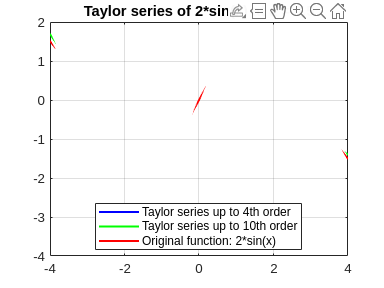

fplot(T_4,'b','LineWidth',1.5);
hold on;
fplot(T_10,'g','LineWidth',1.5);
hold on;
fplot(f,'r','Linewidth',1.5);
hold off;
xlim([-4 4]);
ylim([-4 2]);
grid on
legend('Taylor series up to 4th order', ...
    'Taylor series up to 10th order', ...
    'Original function: 2*sin(x)','Location','Best')
title('Taylor series of 2*sin(x) at a = 0.5');

clc;
% Two differencial equation 
% dy/dt = 4x^2-xy 
% dx/dt = 2y-x^2
% Determine the equilibrium of the system
% For determining equlibrium ponts consider,
% dy/dt = 0 and dx/dt = 0
% The solution x and y will be the equilibrium points of the system
clc;
syms x y
[solx, soly] = solve(4*x^2-x*y == 0, 2*y-x^2 == 0);
disp('Equilibrium points: ')

Equilibrium points: 


E_point1 = [solx(1) soly(1)]

$$E\_point1 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

E_point2 = [solx(2) soly(2)]

$$E\_point2 = \left(\begin{array}{cc} 8 & 32 \end{array}\right)$$

clc;
% Real power P = 10W
% Reactive power, Q = 20 VAR
% Time, t = 24 hours = 86400 sec 
% Apparent power, S is a complex number 
% Electrical energy, E = p*t

P = 10; Q = 20; t = 86400;
% Rectangular form
S_rec = complex(P,Q);
disp('Apparent power in rectangular form: ');

Apparent power in rectangular form: 


S_rec

S_rec = 10.0000 +20.0000i

% Polar form
S_mag = abs(S_rec);
S_angle = angle(S_rec) * (180/pi); % Unit Degree
S_polar = [S_mag, S_angle];
disp('Apparent power in polar form [Magnitude Angle(Degree): ');

Apparent power in polar form [Magnitude Angle(Degree): 


S_polar

S_polar =    22.3607   63.4349


% Electrical energy 
E = P*t 

E = 864000

disp(['Electrical energy: ', num2str(E), ' joule']);

Electrical energy: 864000 joule


clc;

clc;
% Voltage, V = 100<60
% Current, I 3<30
% Impedance, Z = V/I
V_mag = 100;
V_ang = 60;
I_mag = 3;
I_ang = 30;
[Vx, Vy] = pol2cart(V_ang, V_mag);
V_rec = Vx+i*Vy;
[Ix, Iy] = pol2cart(I_ang, I_mag);
I_rec = Ix+i*Iy;
Z_rec = V_rec/I_rec;
disp('Impedance in rectangular form: ')

Impedance in rectangular form: 


Z_rec

Z_rec = 5.1417 -32.9344i

% Polar form
Z_mag = abs(Z_rec);
Z_ang = angle(Z_rec) * (180/pi);
Z_polar = [Z_mag, Z_ang];
disp('Impedance in polar for [Magnitude Angle(Degree)]: ');

Impedance in polar for [Magnitude Angle(Degree)]: 


Z_polar

Z_polar =    33.3333  -81.1266


clc;
% Resistance, R=5 ohms
% Capacitance, C=2 micro F 
% Inductance, L=15 mH
% Frequency, f=60hz 
% Impedance, Z=R+jX = R+j(X_L-X_C)
% Here,
% X_L = Inductive Reactance = omega*L = 2*pi*f*L
% X_C = Capacitive reactnace = 1/(omega*C) = -1/(2*pi*f*C)

R = 5; L = 15*10^(-3); C = 2*10^(-6); f=60;
X_L = 2*pi*f*L;
X_C = -1/(2*pi*f*C);
% Rectangular form
Z_rec = R+i*(X_L-X_C);
disp('Impedance in rectangula form: ');

Impedance in rectangula form: 


Z_rec 

Z_rec = 5.0000e+00 + 1.3319e+03i

% polar form
Z_mag = abs(Z_rec);
Z_ang = angle(Z_rec) * (180/pi);
Z_polar = [Z_mag, Z_ang];
disp('Impedance in polar form [Magnitude Angle(Degree)]: ');

Impedance in polar form [Magnitude Angle(Degree)]: 


Z_polar

Z_polar = 1.0e+03 *

    1.3320    0.0898
